# 'triangle' method usage example

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic


#### Povlab object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Scene

pl.scene_begin('scene_file', 'triangle.pov', 'image_file', 'triangle.png');
    pl.include("shapes");
    pl.global_settings("assumed_gamma 1");
    
    % Camera
    pl.camera('angle', 50, 'location', [12 10 7], 'look_at', [0 0 0]);
    
    % Lights
    pl.light('location', [12  10  7], 'color', [1.5 1.5 1.5]);
    pl.light('location', [-12  -10  7], 'color', [1.5 1.5 1.5], 'shadowless', true);
    pl.light('location', [10  10 10], 'color', [2 2 2]);
    pl.light('location', [30 -30 30], 'color', [2 2 2]);
    
    % Axis
    pl.axis('length', [6 6 5], 'radius', 0.04);

    % Textures
    finish = "phong 1 reflection {0.02 metallic 0.8}";
    tex_grey   = pl.declare("tex_grey",   pl.texture('pigment_odd', [0.05 0.05 0.05], 'pigment_even', [3 3 3], 'finish', finish));
    tex_green  = pl.declare("tex_green",  pl.texture('pigment', [0.1 2.5 0.3], 'finish', finish));
    tex_pink   = pl.declare("tex_pink",   pl.texture('pigment', [0.8 0.2 0.3], 'finish', finish));
    tex_yellow = pl.declare("tex_yellow", pl.texture('pigment', [2 2 0], 'finish', finish));
    
    % Plane
    pl.plane('normal', [0,0,1], 'limits', [-5 -5 5 5], 'texture', tex_grey);

    % Objects
    pl.triangle('p1', [0 0 0], 'p2', [4 4 1],  'p3', [0 5 4], 'texture', tex_pink);
    pl.triangle('p1', [0 0 0], 'p2', [4 -2 3], 'p3', [5 2 2], 'texture', tex_green);
    pl.triangle('p1', [0 0 0], 'p2', [4 -2 3], 'p3', [5 2 2], 'texture', tex_yellow, 'rotate', [0 0 -145], 'scale', [1 1 0.5] );

pl.scene_end();

#### Render and display

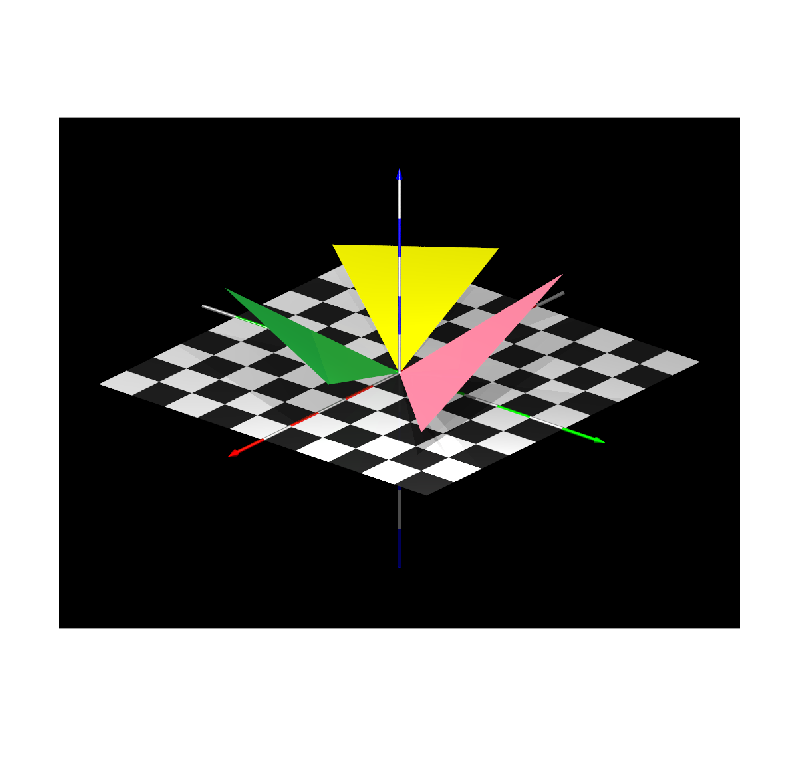

image = pl.render();
imshow(image);

#### Elapsed time

toc

Elapsed time is 4.946813 seconds.
